# PR曲線による平均適合率の計算について、自分で書いて確認してみる

この記事では、物体検出を行ったときの精度の指標である、平均適合率について扱います。

この記事を執筆するにあたって、原田達也先生の「画像認識」の7.7.2 平均適合率を参考にいたしました。詳しくはこの本をご参照ください。

[https://www.amazon.co.jp/dp/B0756V3TPG/ref=dp-kindle-redirect?_encoding=UTF8&btkr=1](https://www.amazon.co.jp/dp/B0756V3TPG/ref=dp-kindle-redirect?_encoding=UTF8&btkr=1)

## はじめに

ここでいう物体検出とは、以下の図のように、画像中から関心のある物体を検出することです。検出された物体は黄色の箱（以下、**バウンディングボックス**という）で囲まれていることがわかります。また、下の図では、あえて少し車の領域からずらしてバウンディングボックスを作成しています。

　これを検出結果だとすると、この検出の結果を評価するためには、どうのようにすればよいでしょうか。代表的な物体検出の評価として、**平均適合率**によるものが挙げられます。この記事では、この平均適合率について勉強したことをまとめます。

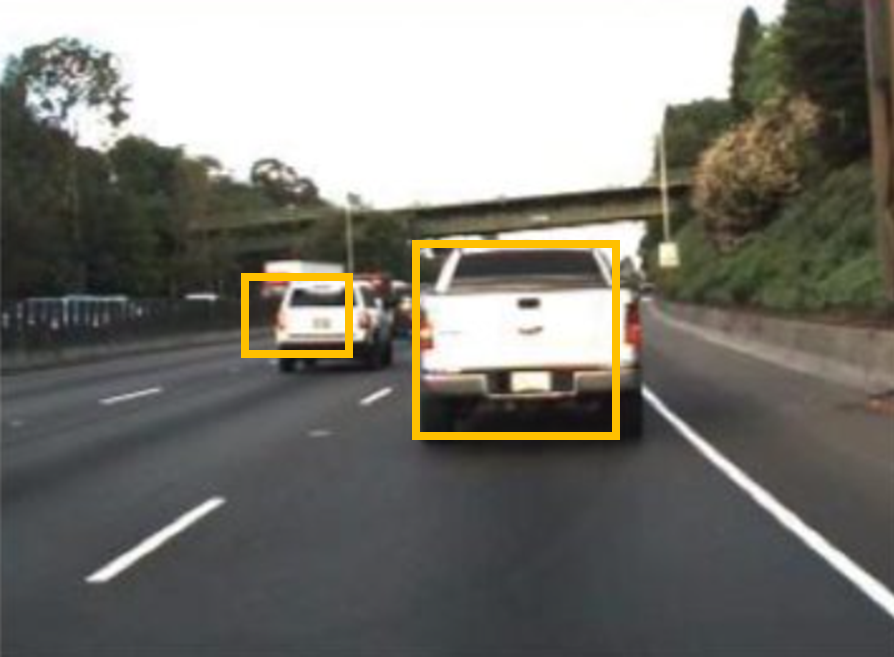

画像出典：[What Is Object Detection? 3 things you need to know](https://jp.mathworks.com/discovery/object-detection.html) (以下も同様）

## 物体検出の評価をするときの準備

物体検出の性能を評価するためには、まず、正解となるバウンディングボックスの情報が必要です。下の図では赤色のバウンディングボックスで示されています。

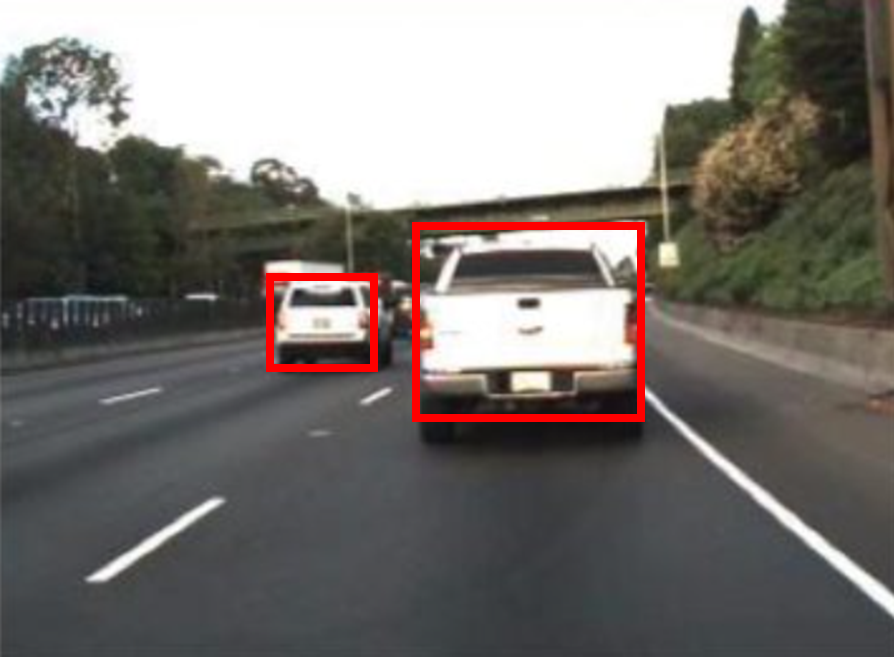

はじめに示した、検出の結果（黄色のバウンディングボックス）と比べると、より車の領域を正しく捉えられていることがわかります。

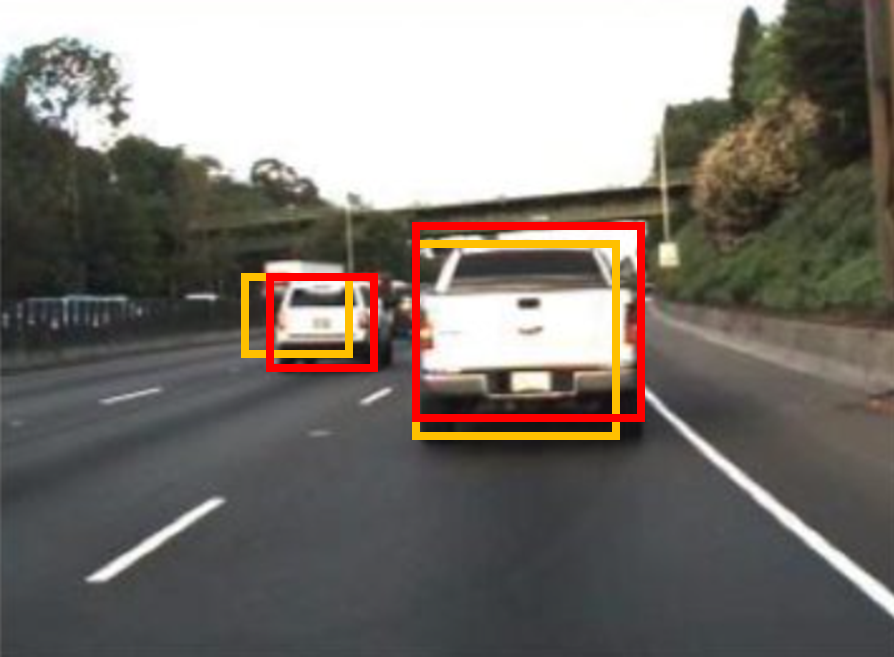

このように、平均適合率では、正解データとしてのバウンディングボックスと、検出の結果としてのバウンディングボックスを比べ、計算していきます。

## IoUについて

上の図では、２つの自動車を検出していて、どちらの検出も正しく行えていそうです。ただ、以下の例のように、検出結果（黄色）が、正解のバウンディングボックス（赤）に比べて、非常に小さかったり、横方向にずれていると、この検出結果は正しくないように見えます。

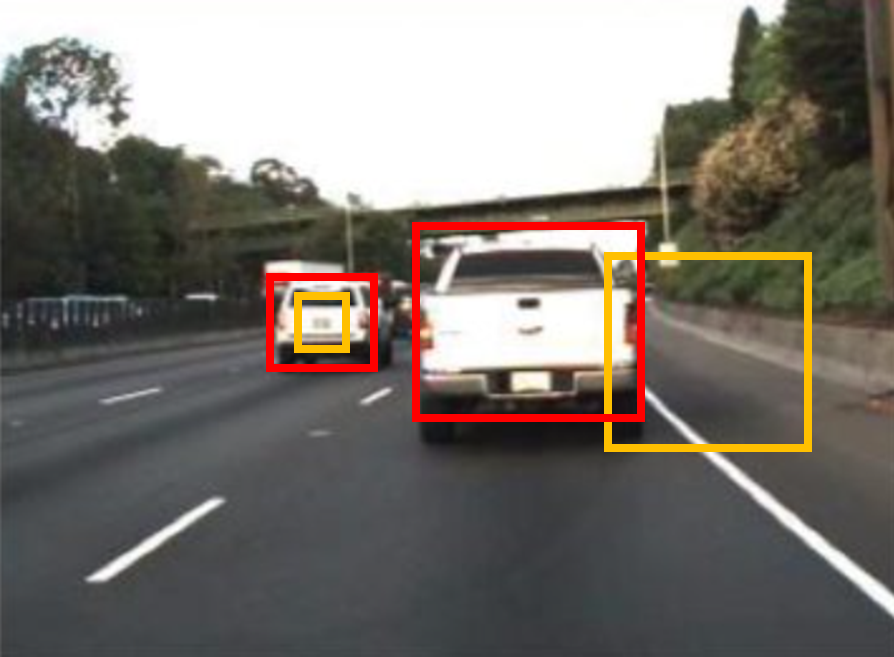

ここで、IoU (Intersection over Union)と呼ばれる指標を導入します。図示すると下のようになります。IoUは、正解と予測のバウンディングボックスの共通の重なり部分を、2つのバウンディングボックスを重ねたときの総面積で割り算したときの結果を指します。一般的には、このIoUの値が0.5以上だと正しく検出ができたとみなす場合が多いです。ただ、その時々の要求精度や、扱う物体によっては、0.5以外が良い場合もあるかもしれません。この値を他の値にすれば、もちろん後に計算する平均適合率の値も変化します。

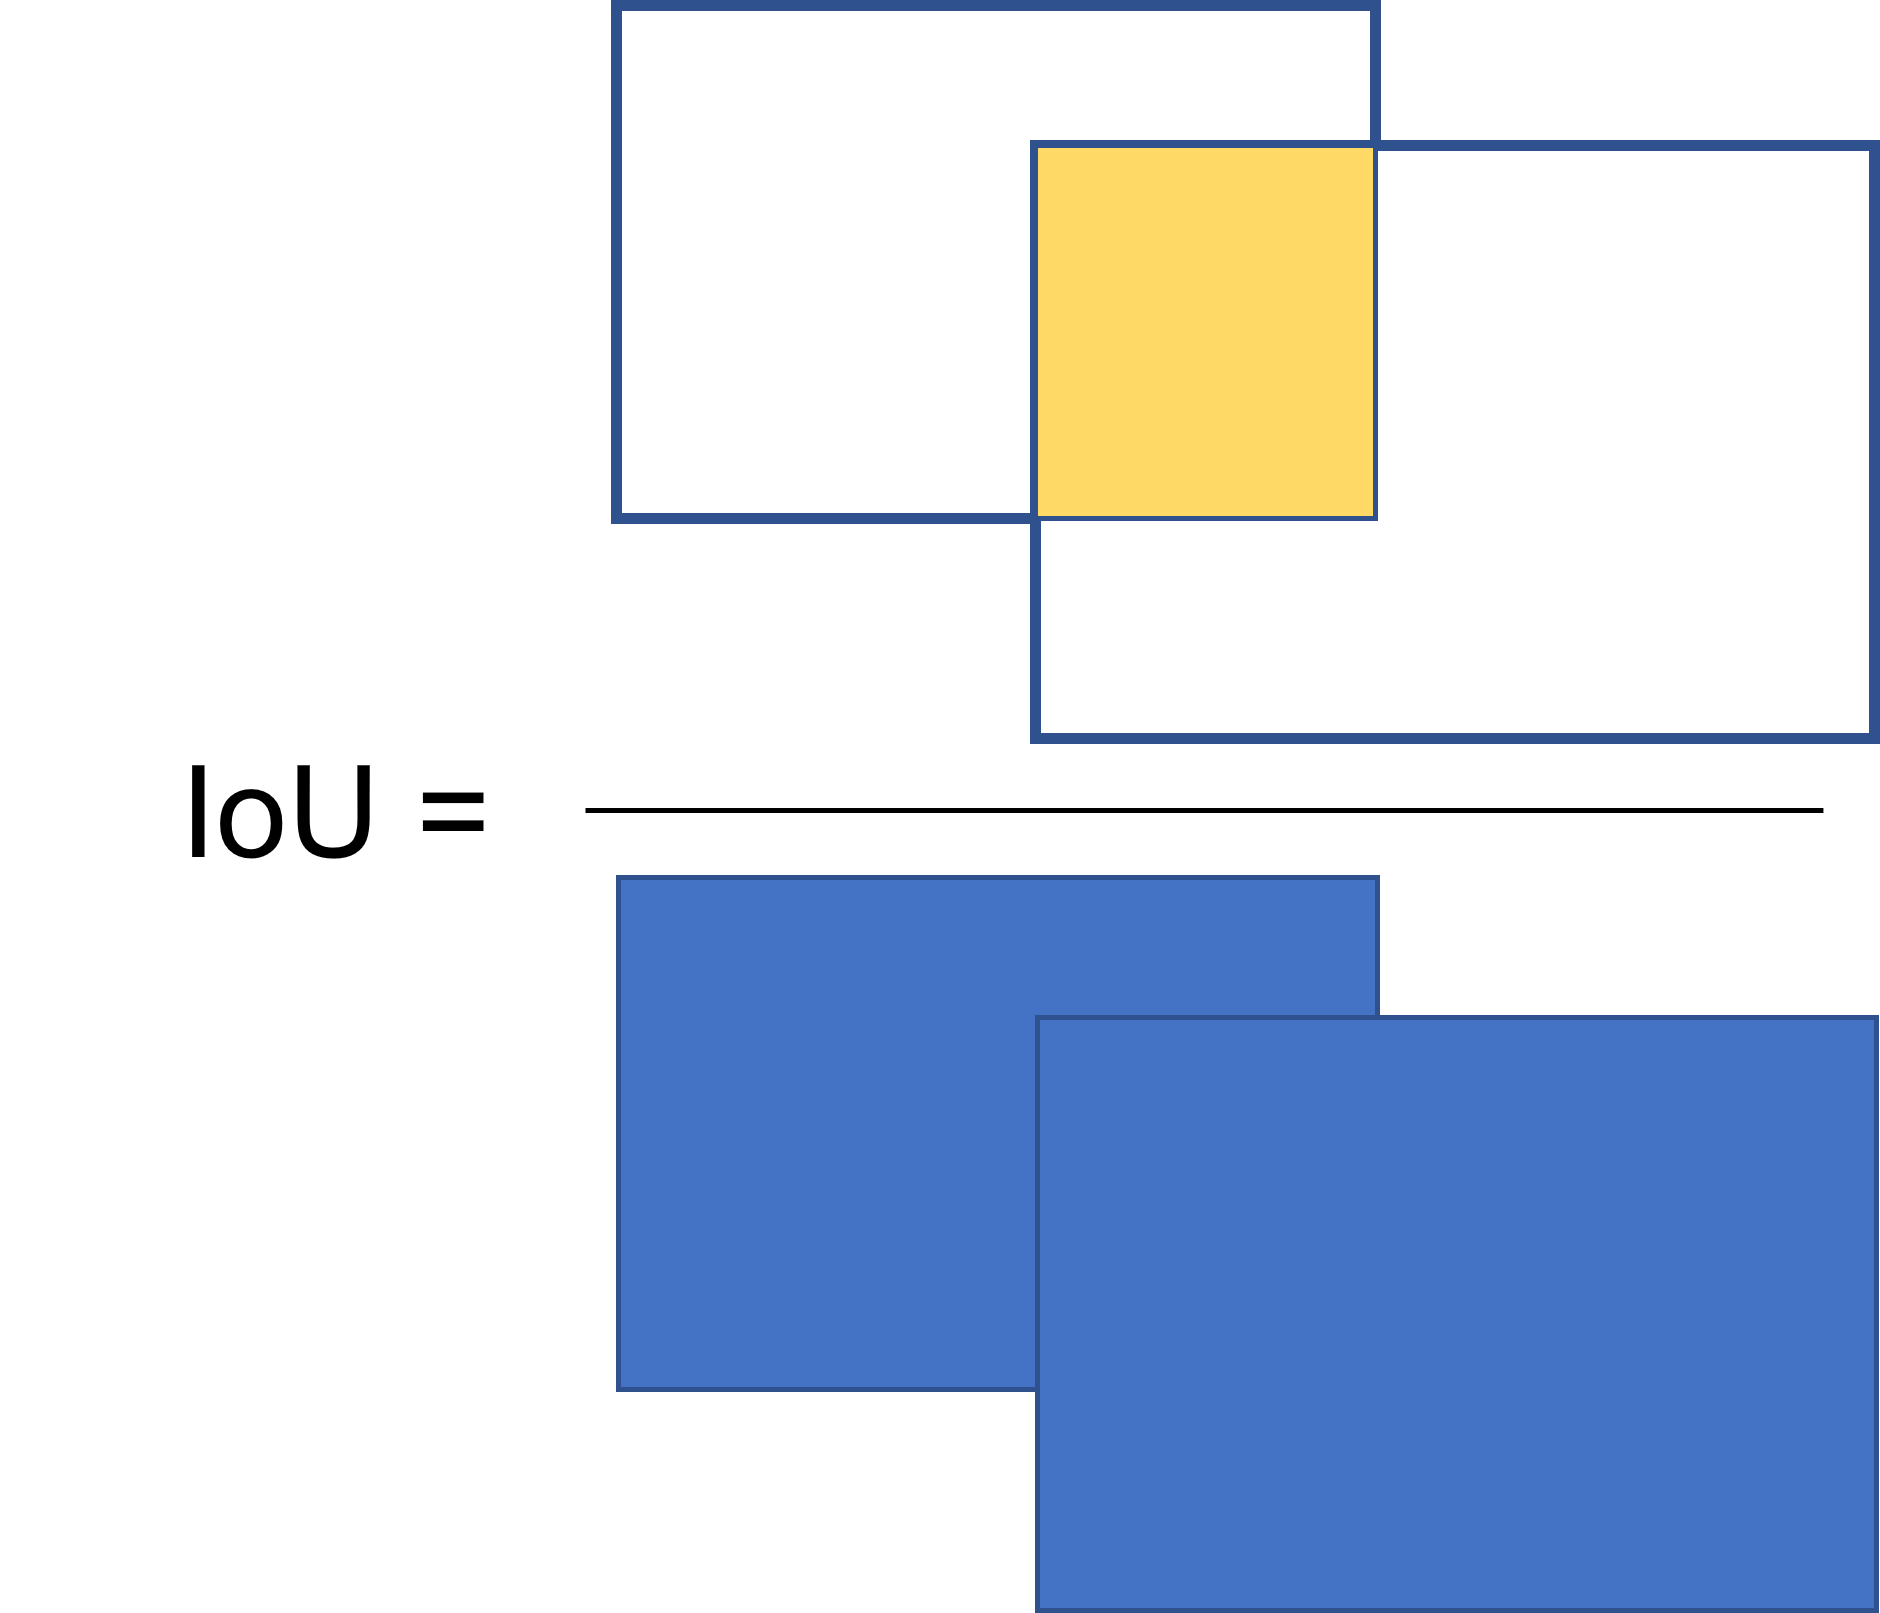

## recall/precisionについて

上で説明したIoUに加え、`recall`や`precision`といった指標も必要になってきます。recallとprecisionについては、以下の記事などがわかりやすかったです。

**分類のための指標(PrecisionとRecall)の解説**https://engineering.mobalab.net/2020/12/03/%E5%88%86%E9%A1%9E%E3%81%AE%E3%81%9F%E3%82%81%E3%81%AE%E6%8C%87%E6%A8%99precision%E3%81%A8recall%E3%81%AE%E8%A7%A3%E8%AA%AC/

**Precision, Recall, F値の気持ちを解釈してみる**

[https://qiita.com/dl_from_scratch/items/4efdf647b397d794cd67](https://qiita.com/dl_from_scratch/items/4efdf647b397d794cd67)

この平均適合率において重要な理解としては、

- recall：すべての正解のバウンディングボックスのうち、何個（何％）検出できたか

- precision：検出したバウンディングボックスのうち、何個（何％）が正しいか

ということなのではないかと個人的には思います。

clear;clc;close all
thresh=0.5; % threshold over which the detection is judged as "correct"
all_score=[];
load groundTruth.mat
load detectionResults.mat
[ap,recall_matlabFunc,precision_matlabFunc] = evaluateDetectionPrecision(detectionResults, groundTruth, 0.5);
ap

ap = 0.7712

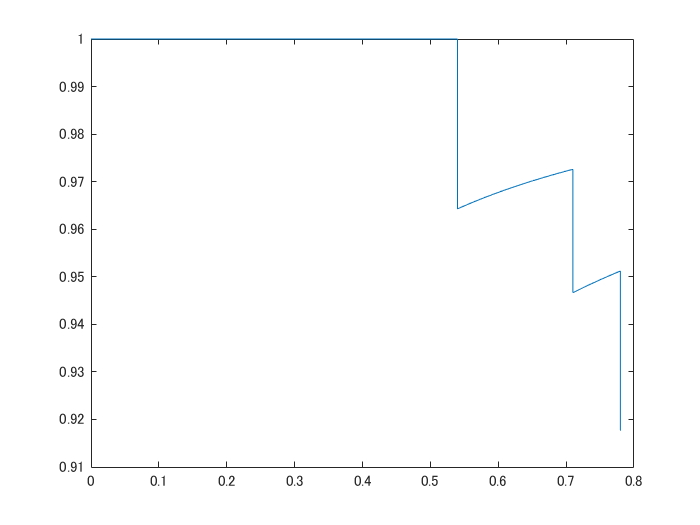

figure;plot(recall_matlabFunc,precision_matlabFunc)


num=0;
for i=1:size(detectionResults,1)
    scoreAll=detectionResults(i,2);
    scoreAll=numel(scoreAll.Scores{1});
    num=num+scoreAll;
end
num

num = 85



numgt=0;
aa=groundTruth.vehicle;
for i=1:size(groundTruth,1)
    bb=aa{i};
    numgt=numgt+size(bb,1);
end
numgt

numgt = 100


bbox_ind=1;
for i=1:size(detectionResults,1)
    bboxes=detectionResults(i,1);
    bboxes_i=bboxes.Boxes{1};
    
    
    % scoreを追加
    scores=detectionResults(i,2);
    scores_i=scores.Scores;
    if size(bboxes_i,1)>0
        for j=1:size(bboxes_i,1)
            b=a.vehicle;
            dummy=bboxes_i(j,:);
            score_j=scores_i{1};
            catb=cat(1,b{i});
            overlapRatio = bboxOverlapRatio(dummy,catb,'Union');
            overlapRatioMax = max(overlapRatio);
            if overlapRatioMax > thresh
                all_score(bbox_ind)=score_j(j);
                iscorrect(bbox_ind)=1;
            else
                all_score(bbox_ind)=score_j(j);
                iscorrect(bbox_ind)=0;
            end
                if bbox_ind==26
                    overlapRatioMax
                    j
                end
                bbox_ind=bbox_ind+1;
                
        end
    end

end

overlapRatioMax = 0.6348

j = 1

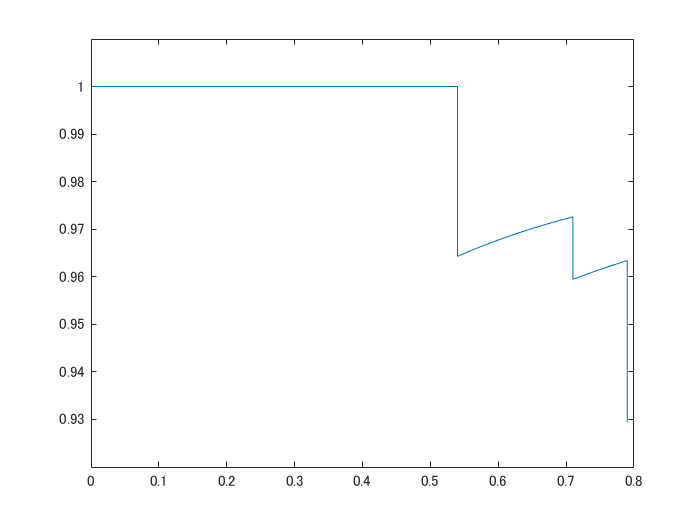

recall=0;
precision=1;

[all_score,scoreInd] = sort(all_score,'descend');
iscorrect=iscorrect(scoreInd);
for k=1:bbox_ind-1
    if iscorrect(k)==1
        recall(k+1)=recall(k)+1/numgt;
        precision(k+1)=sum(iscorrect(1:k)/k);
    else
        recall(k+1)=recall(k);
        precision(k+1)=sum(iscorrect(1:k)/k);
    end
end

figure;plot(recall,precision)


v=1;ap=0;
for l=1:numel(precision)-1
    precision_i=precision(l);
    ap=ap+(recall(l+1)-recall(l))*precision_i;
end
ap

ap = 0.7816